lab9

**Zadanie 3**

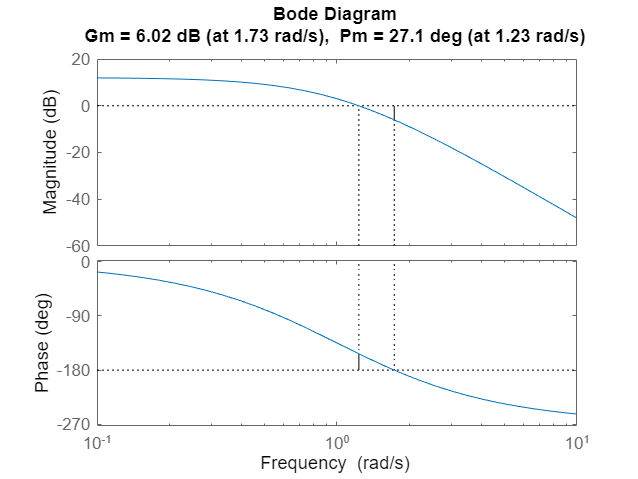

obiekt_1:


k: 4


Zapas modułu: 1.9999
Zapas fazy: 0.47298[rad]


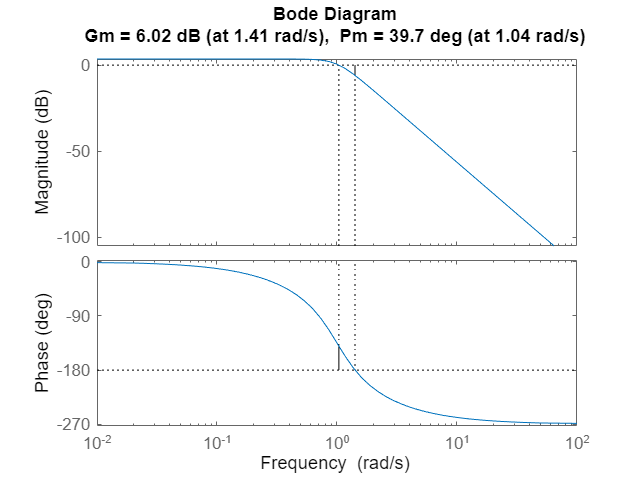

obiekt_2


k: 1.5


Zapas modułu: 1.9999
Zapas fazy: 0.6929[rad]


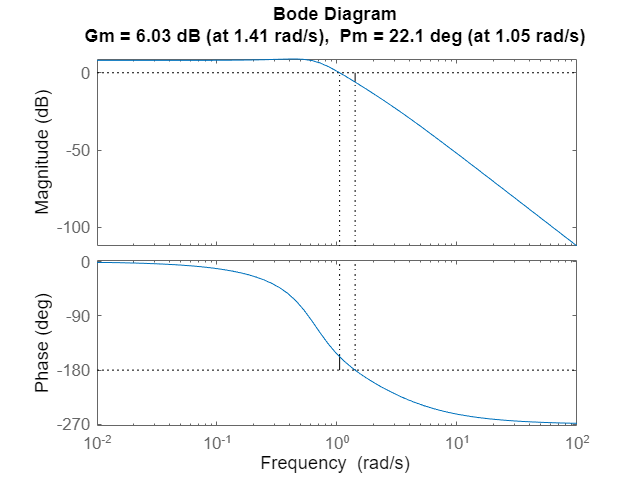

obiekt_3:


k: 1.25


Zapas modułu: 1.9999
Zapas fazy: 0.38572[rad]


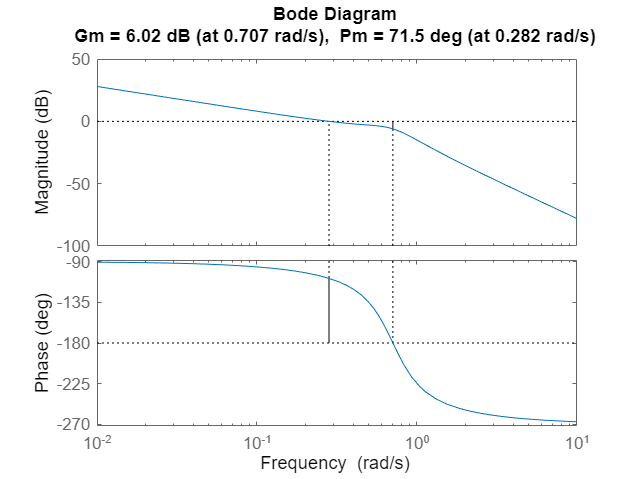

obiekt_4:


k: 0.25


Zapas modułu: 1.9999
Zapas fazy: 1.2479[rad]


licz1 = [1];
mian1 = [1 3 3 1];
licz2 = [1];
mian2 = [1 2 2 1];
licz3 = [2];
mian3 = [1 3 2 1];
licz4 = [1];
mian4 = [2 1 1 0];

obiekt_1 = tf(licz1, mian1);
obiekt_2 = tf(licz2, mian2);
obiekt_3 = tf(licz3, mian3);
obiekt_4 = tf(licz4, mian4);


obiekty = [obiekt_1 obiekt_2 obiekt_3 obiekt_4];
obiekty_nazwy = ["obiekt_1:" "obiekt_2" "obiekt_3:" "obiekt_4:"];

wartosci_k = [4 1.5 5/4 1/4];

Gm = [6.02 6.02 6.02 6.02];
Pm = [27.1 39.7 22.1 71.5];

i = 1;
for k = wartosci_k
    figure
    G_r = k;
    margin(G_r * obiekty(i))
    disp(obiekty_nazwy(i))
    disp("k: " + k)
    wyswietl_zapas_modulu_i_fazy(Gm(i), Pm(i))

    i = i + 1;

end

**Zadanie 4**

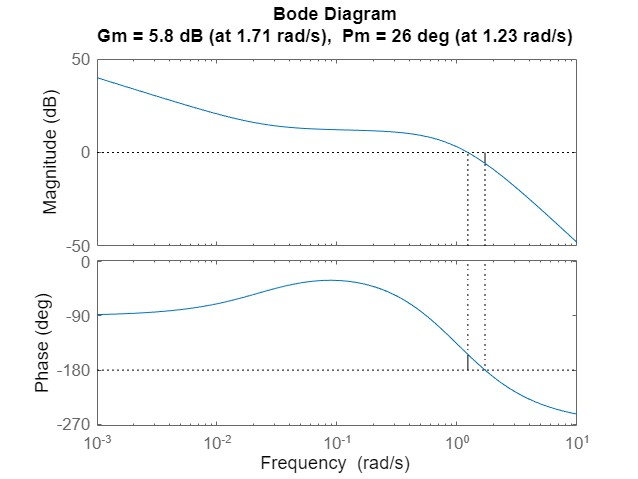

obiekt_1:


k: 4 ; alpha: 0.1


Zapas modułu: 1.9498
Zapas fazy: 0.45379[rad]


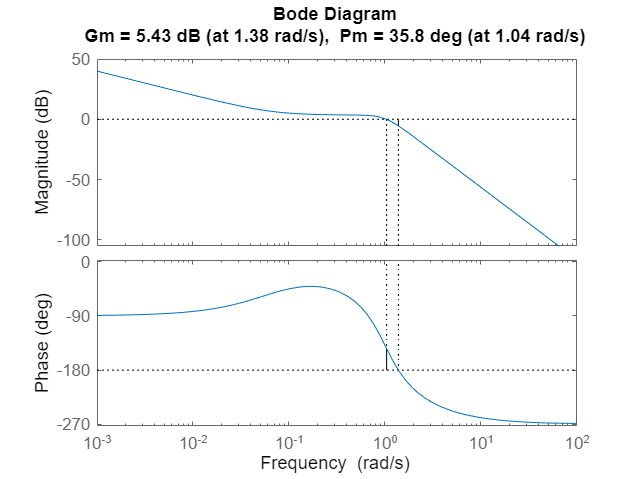

obiekt_2


k: 1.5 ; alpha: 0.1


Zapas modułu: 1.8685
Zapas fazy: 0.62483[rad]


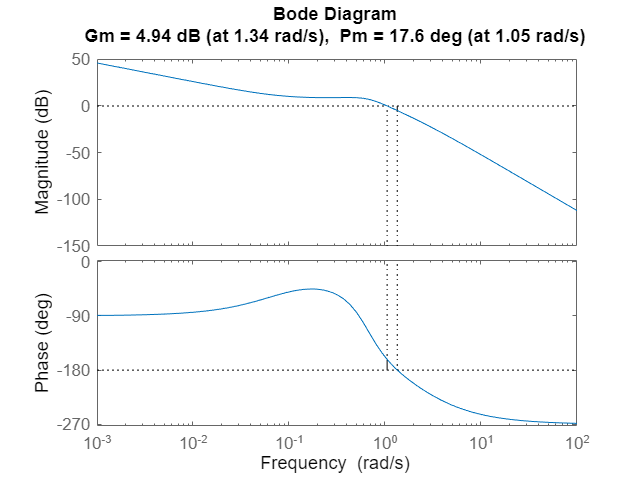

obiekt_3:


k: 1.25 ; alpha: 0.1


Zapas modułu: 1.7681
Zapas fazy: 0.30718[rad]


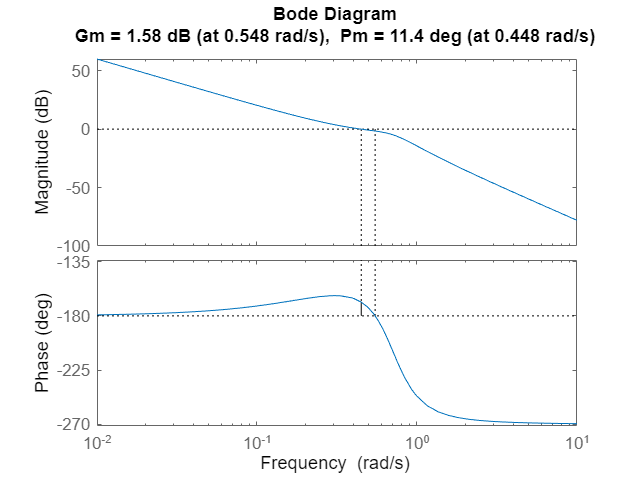

obiekt_4:


k: 0.25 ; alpha: 0.1


Zapas modułu: 1.1995
Zapas fazy: 0.19897[rad]


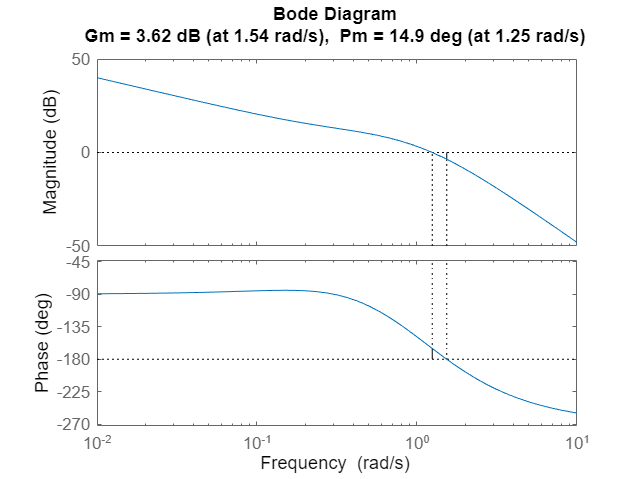

obiekt_1:


k: 4 ; alpha: 1


Zapas modułu: 1.5171
Zapas fazy: 0.26005[rad]


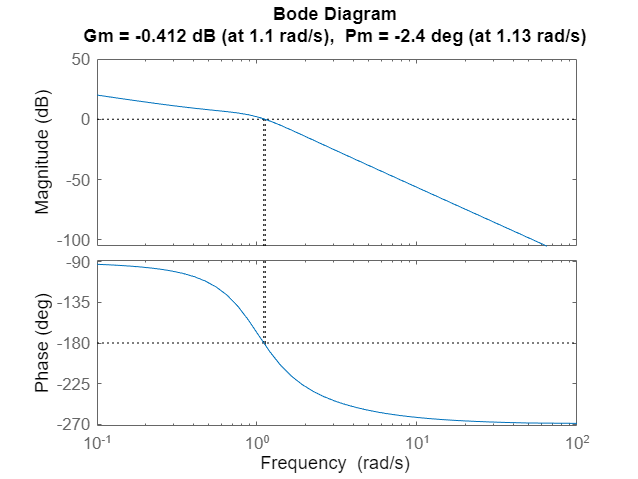

obiekt_2


k: 1.5 ; alpha: 1


Zapas modułu: 0.95367
Zapas fazy: -0.041888[rad]


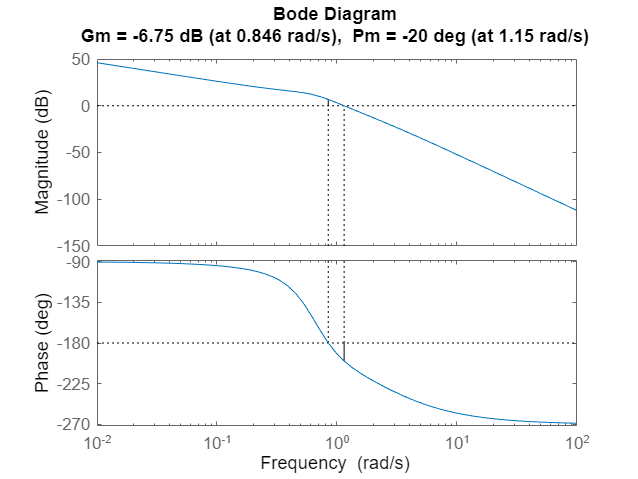

obiekt_3:


k: 1.25 ; alpha: 1


Zapas modułu: 0.45973
Zapas fazy: -0.34907[rad]


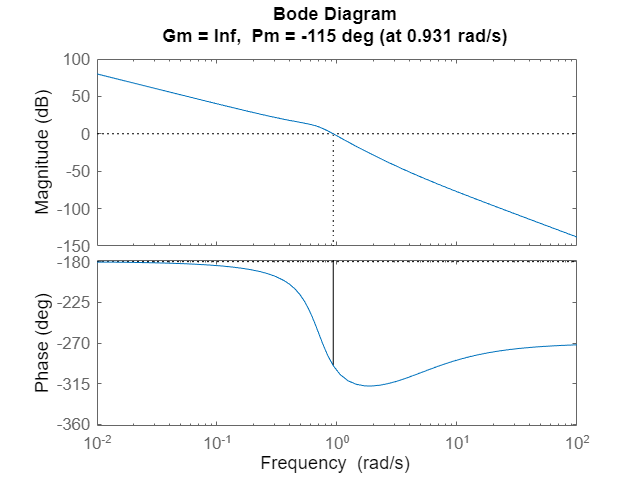

obiekt_4:


k: 0.25 ; alpha: 1


Zapas modułu: 0
Zapas fazy: -2.0071[rad]


clear G_r Gm Pm

Gm = [5.8 5.43 4.95 1.58 3.62 -0.412 -6.75 -inf];
Pm = [26 35.8 17.6 11.4 14.9 -2.4 -20 -115];

j = 0;
for alpha = [0.1 1]
    i = 1;
    for k = wartosci_k
        figure 
        G_r = tf([k alpha], [1 0]);
        margin(G_r * obiekty(i))
        disp(obiekty_nazwy(i))
        disp("k: " + k + " ; alpha: " + alpha)
        wyswietl_zapas_modulu_i_fazy(Gm(i + j), Pm(i + j))

        i = i + 1;

    end
    j = j + 4;
end

**Zadanie 5**

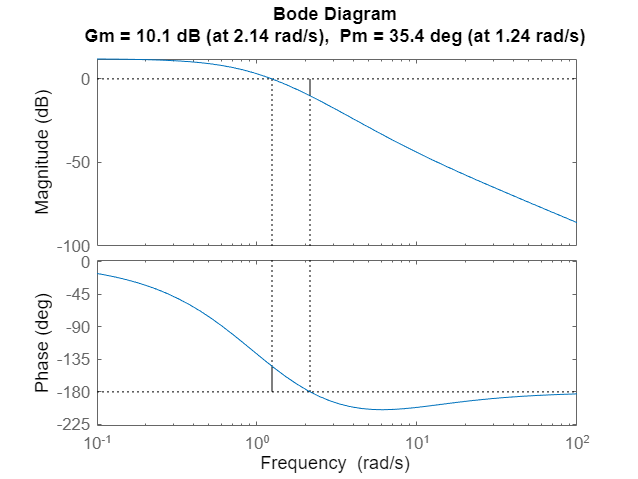

obiekt_1:


k: 4 ; beta: 0.5


Zapas modułu: 3.1989
Zapas fazy: 0.61785[rad]


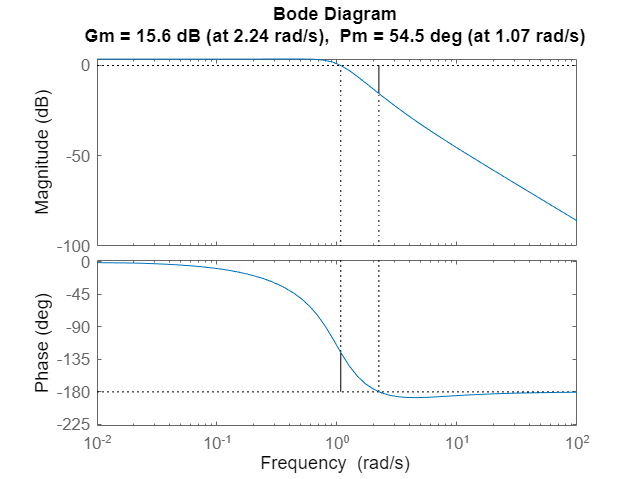

obiekt_2


k: 1.5 ; beta: 0.5


Zapas modułu: 6.0256
Zapas fazy: 0.9512[rad]


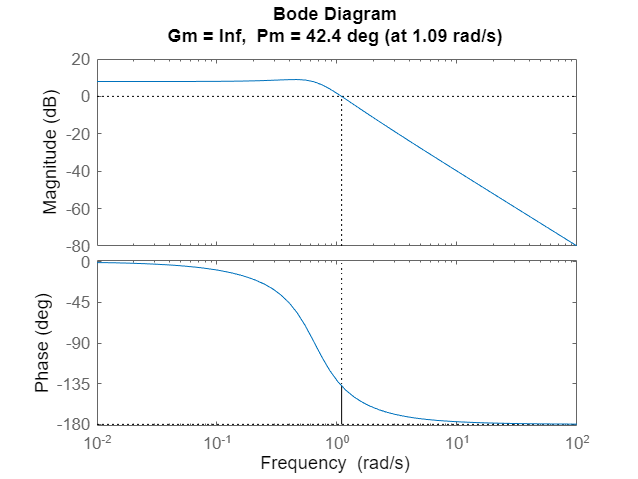

obiekt_3:


k: 1.25 ; beta: 0.5


Zapas modułu: Inf
Zapas fazy: 0.74002[rad]


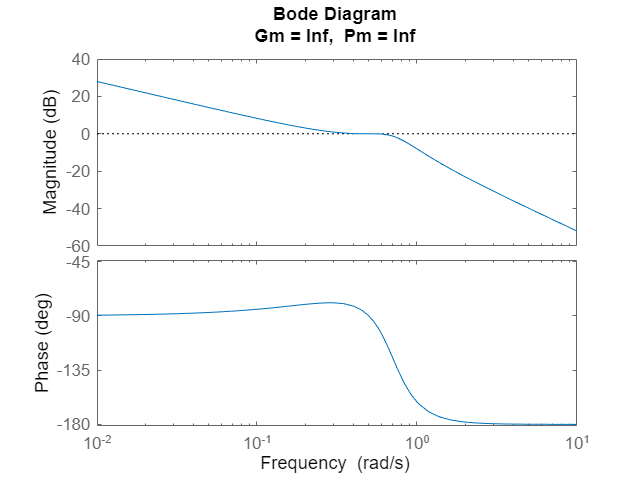

obiekt_4:


k: 0.25 ; beta: 0.5


Zapas modułu: Inf
Zapas fazy: 1.5708[rad]


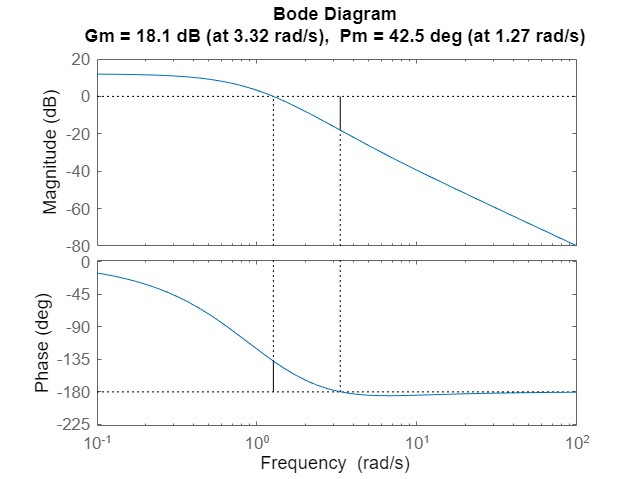

obiekt_1:


k: 4 ; beta: 1


Zapas modułu: 8.0353
Zapas fazy: 0.74176[rad]


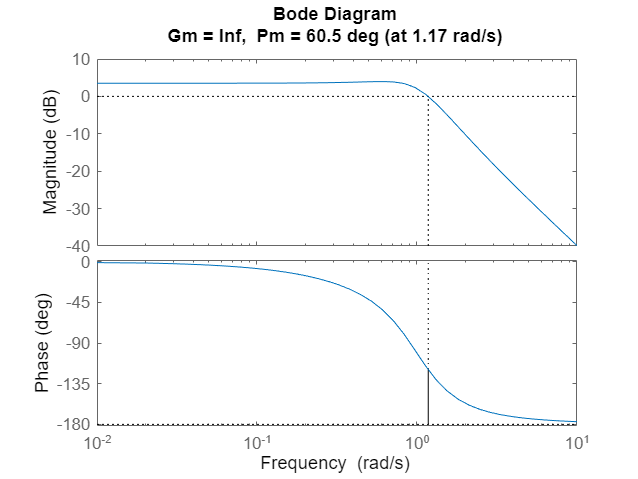

obiekt_2


k: 1.5 ; beta: 1


Zapas modułu: Inf
Zapas fazy: 1.0559[rad]


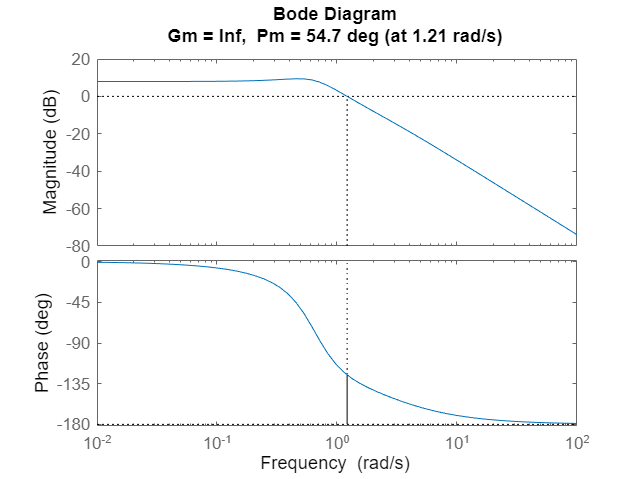

obiekt_3:


k: 1.25 ; beta: 1


Zapas modułu: Inf
Zapas fazy: 0.9547[rad]


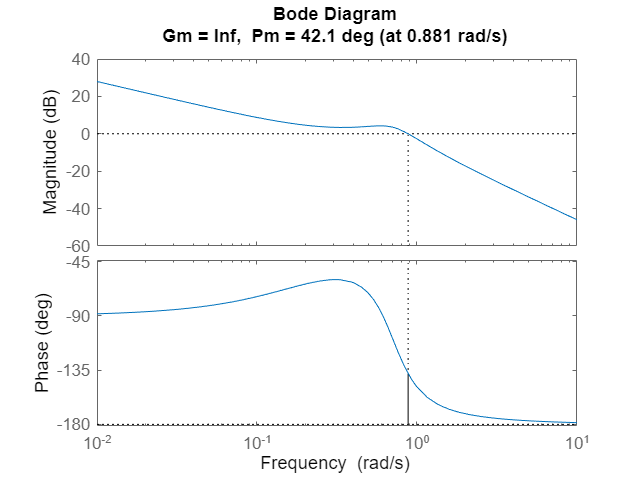

obiekt_4:


k: 0.25 ; beta: 1


Zapas modułu: Inf
Zapas fazy: 0.73478[rad]


clear G_r Gm Pm

Gm = [10.1 15.6 inf inf 18.1 inf inf inf];
Pm = [35.4 54.5 42.4 90 42.5 60.5 54.7 42.1];

j = 0;
for beta = [0.5 1]
    i = 1;
    for k = wartosci_k
        figure 
        G_r = tf([beta k], [0 1]);
        margin(G_r * obiekty(i))
        disp(obiekty_nazwy(i))
        disp("k: " + k + " ; beta: " + beta)
        wyswietl_zapas_modulu_i_fazy(Gm(i + j), Pm(i + j))

        i = i + 1;

    end
    j = j + 4;
end

**Zadanie 6**

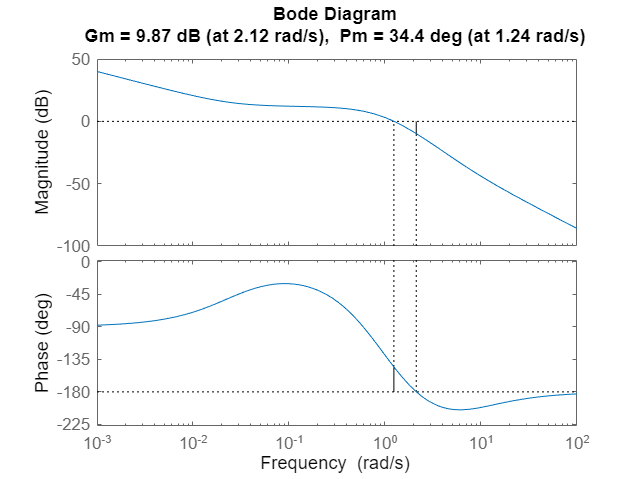

obiekt_1:


k: 4 ; alpha: 0.1 ; beta: 0.5


Zapas modułu: 3.1153
Zapas fazy: 0.60039[rad]


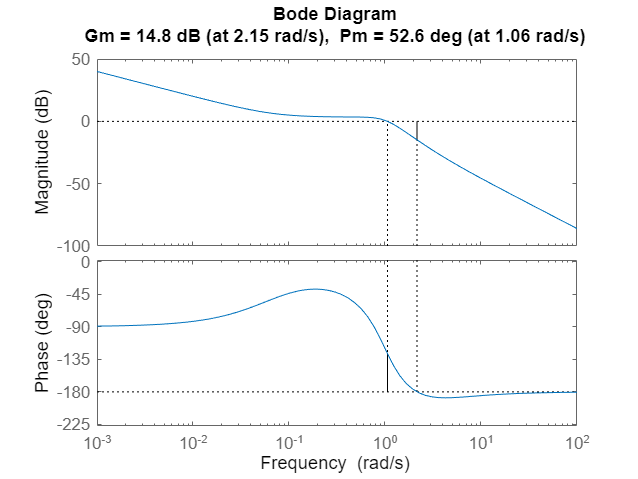

obiekt_2


k: 1.5 ; alpha: 0.1 ; beta: 0.5


Zapas modułu: 5.4954
Zapas fazy: 0.91804[rad]


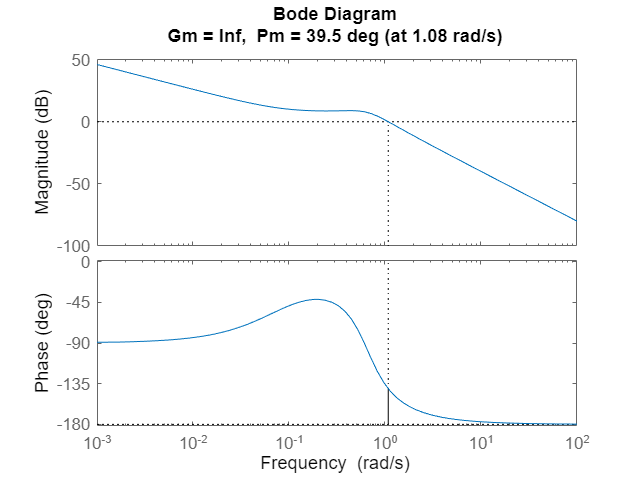

obiekt_3:


k: 1.25 ; alpha: 0.1 ; beta: 0.5


Zapas modułu: Inf
Zapas fazy: 0.68941[rad]


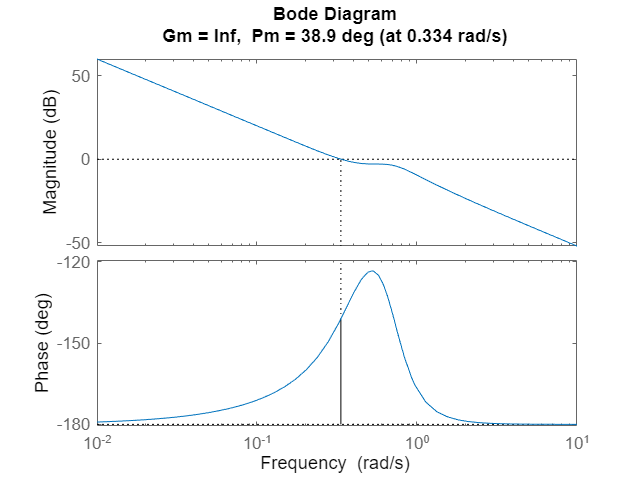

obiekt_4:


k: 0.25 ; alpha: 0.1 ; beta: 0.5


Zapas modułu: 0
Zapas fazy: 0.67893[rad]


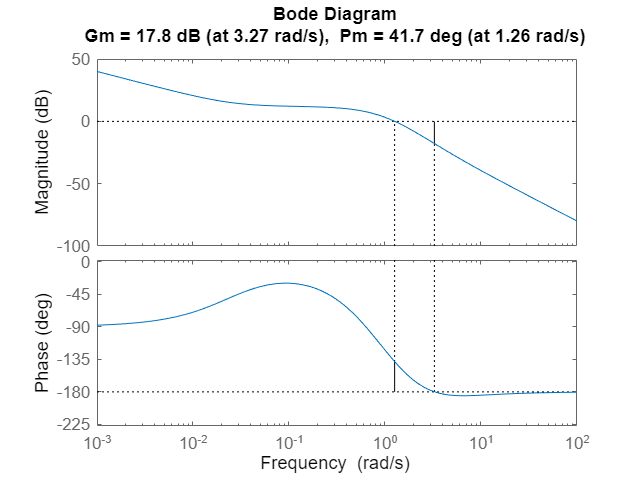

obiekt_1:


k: 4 ; alpha: 0.1 ; beta: 1


Zapas modułu: 3.1153
Zapas fazy: 0.60039[rad]


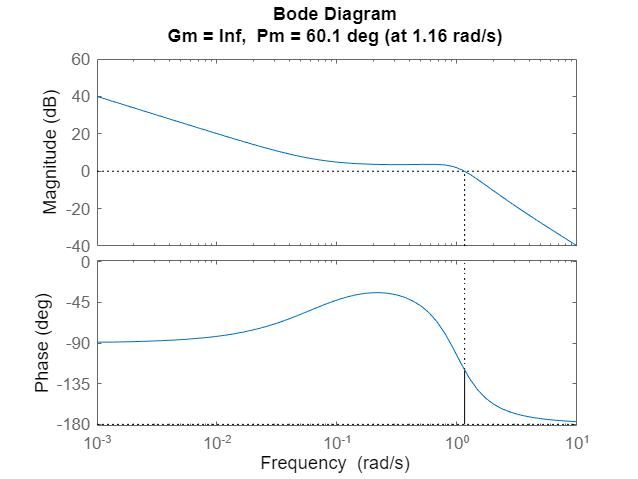

obiekt_2


k: 1.5 ; alpha: 0.1 ; beta: 1


Zapas modułu: 5.4954
Zapas fazy: 0.91804[rad]


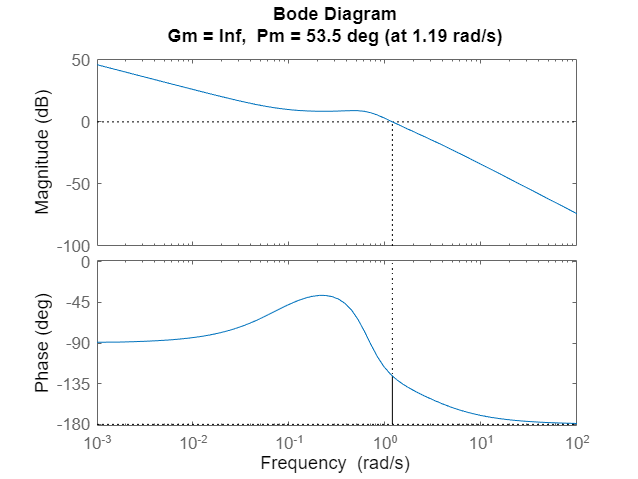

obiekt_3:


k: 1.25 ; alpha: 0.1 ; beta: 1


Zapas modułu: Inf
Zapas fazy: 0.68941[rad]


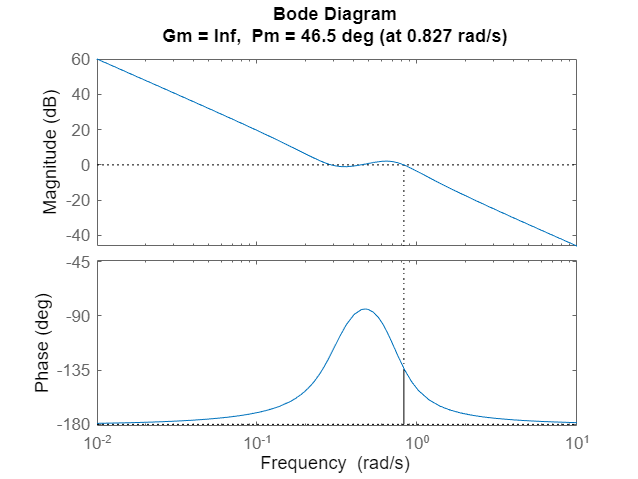

obiekt_4:


k: 0.25 ; alpha: 0.1 ; beta: 1


Zapas modułu: 0
Zapas fazy: 0.67893[rad]


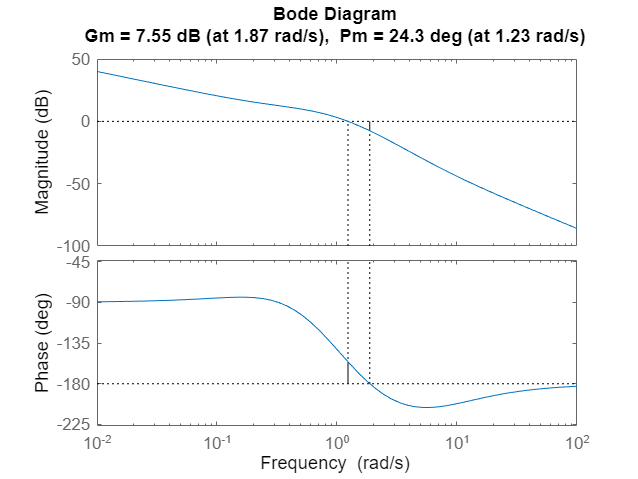

obiekt_1:


k: 4 ; alpha: 1 ; beta: 0.5


Zapas modułu: 2.3851
Zapas fazy: 0.42412[rad]


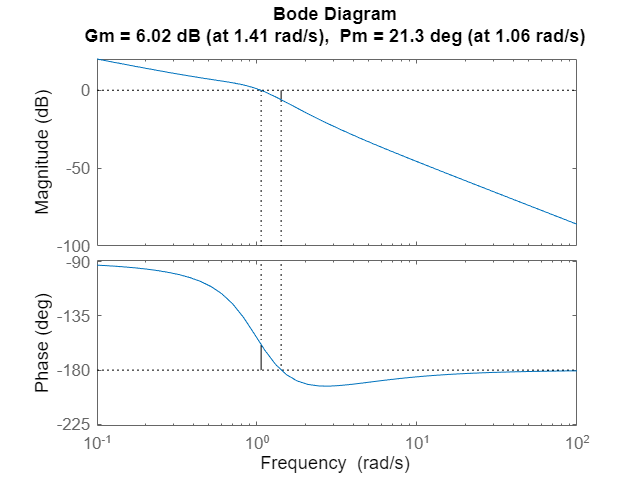

obiekt_2


k: 1.5 ; alpha: 1 ; beta: 0.5


Zapas modułu: 1.9999
Zapas fazy: 0.37176[rad]


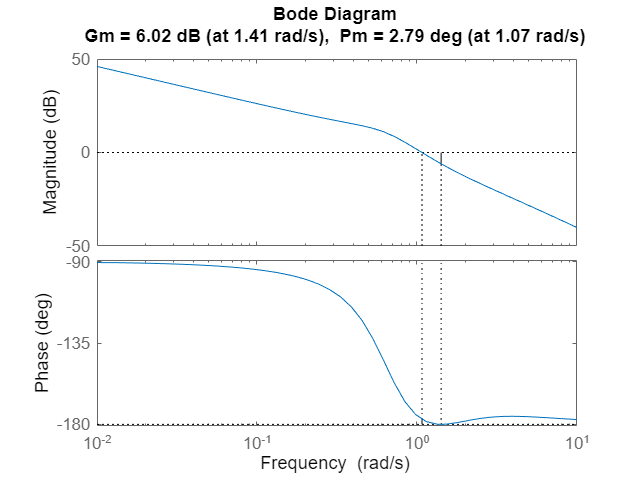

obiekt_3:


k: 1.25 ; alpha: 1 ; beta: 0.5


Zapas modułu: 1.9999
Zapas fazy: 0.048695[rad]


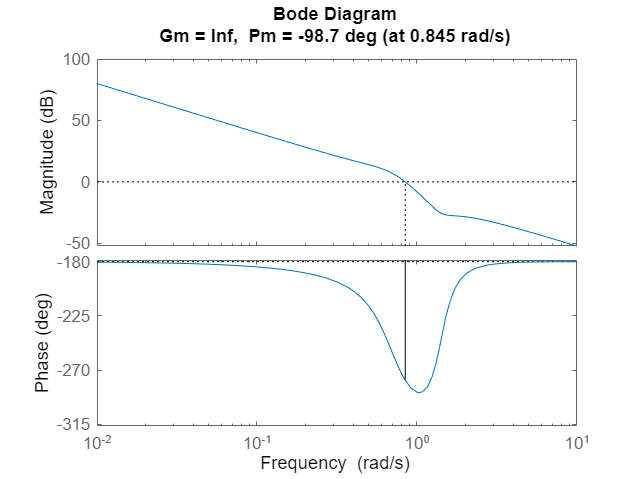

obiekt_4:


k: 0.25 ; alpha: 1 ; beta: 0.5


Zapas modułu: 0
Zapas fazy: -1.7226[rad]


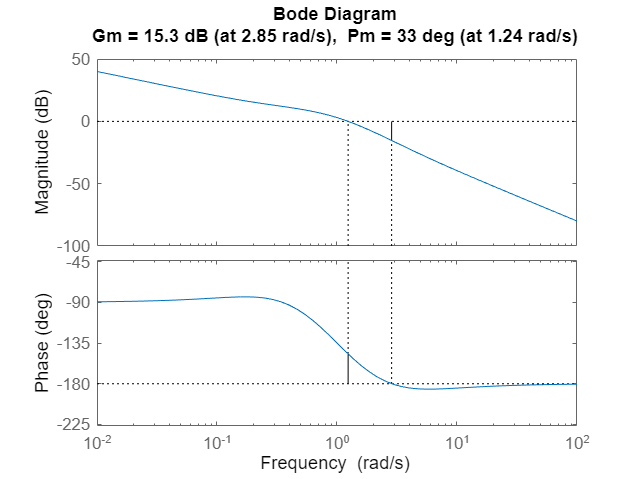

obiekt_1:


k: 4 ; alpha: 1 ; beta: 1


Zapas modułu: 2.3851
Zapas fazy: 0.42412[rad]


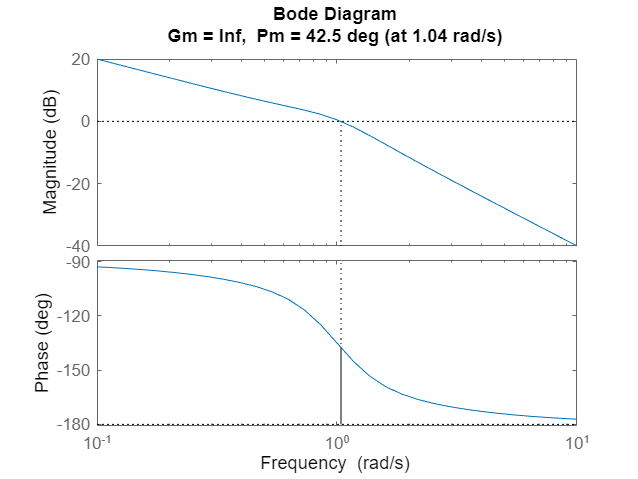

obiekt_2


k: 1.5 ; alpha: 1 ; beta: 1


Zapas modułu: 1.9999
Zapas fazy: 0.37176[rad]


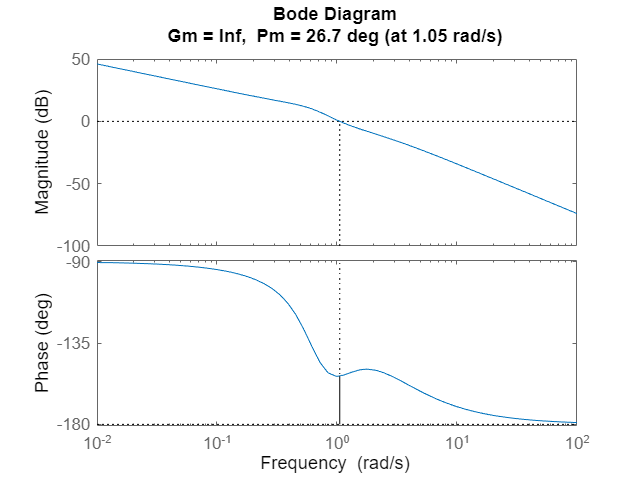

obiekt_3:


k: 1.25 ; alpha: 1 ; beta: 1


Zapas modułu: 1.9999
Zapas fazy: 0.048695[rad]


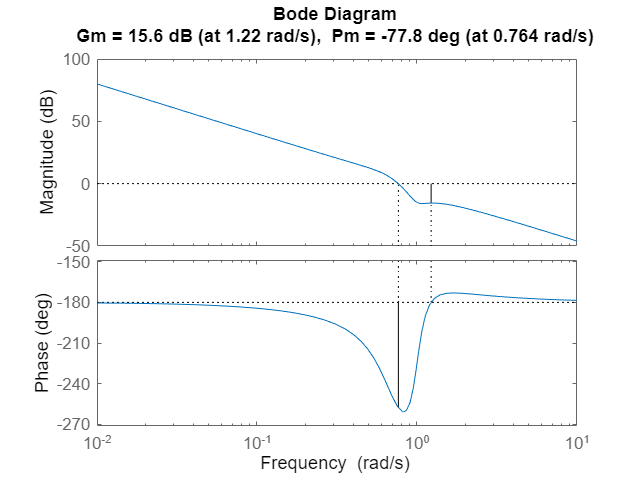

obiekt_4:


k: 0.25 ; alpha: 1 ; beta: 1


Zapas modułu: 0
Zapas fazy: -1.7226[rad]


clear G_r Gm Pm

Gm = [9.87 14.8 inf -inf 17.8 inf inf -inf 7.55 6.02 6.02 -inf 15.3 inf inf 15.6];
Pm = [34.4 52.6 39.5 38.9 41.7 60.1 53.5 46.5 24.3 21.3 2.79 -98.7 33 42.5 26.7 -77.8];

j = 0;
for alpha = [0.1 1]
    jj = 0;
    for beta = [0.5 1]
        i = 1;
        for k = wartosci_k
            figure 
            G_r = tf([beta k alpha], [0 1 0]);
            margin(G_r * obiekty(i))
            disp(obiekty_nazwy(i))
            disp("k: " + k + " ; alpha: " + alpha + " ; beta: " + beta)
            wyswietl_zapas_modulu_i_fazy(Gm(i + j), Pm(i + j))
    
            i = i + 1;
    
        end
        jj = jj +4;

    end


    j = j + 8;
end